# EEGLAB Child Mind Example - ML

#### This tutorial showcases MATLAB Array Datastores for machine learning workflows. 

In this example, a public EEG dataset from the Child Mind Institute is used along with existing VGG-16 (16-layer convolutional neural network) classification model **R-VGG_noNormalization**. The data and labels are already split into its training, testing, and validation for ease of use. Furthermore, we take advantage of the Array Datastore introduced in R2021a for pointing to signal and label data from in-memory data.

## AWS S3 - Environment and Credentials

Set the environment and AWS credentials required to access the Child Mind Institute public data. Notice no access/secret key is required for this example.

setenv('AWS_DEFAULT_REGION', 'us-west-1');
% aws_access_key = '';    % not needed
% aws_secret_key = '';    % not needed
% aws_credentials = aws.auth.basic.BasicAWSCredentials(aws_access_key, aws_secret_key);

## Setting Folder and File

Specifying bucket and folder containing processed data. 

s3_bucket = "s3://childmind/";
folder_test = "matlab/test/";
folder_train = "matlab/train/";
folder_val = "matlab/val/";

% showing information
info_train = dir(s3_bucket+folder_train)

info_train = 71138×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


## Downloading for Local Loading

Use following function to download data for the MATLAB ChildMind example. If it's the first time downloading data, ensure you have good internet connection. This will take few hours.

downloadChildMindData()

% if files exist...
downloadChildMindData()

Test files detected.
Val files detected.
Train files detected.


  ArrayDatastore with properties:

              ReadSize: 1
    IterationDimension: 1
            OutputType: "cell"



ans = 1×1 cell array
    {'s3://childmind/matlab/train/'}


## Loading Local Data

Run this after downloading the files from AWS S3 and have added them to your path. 

% local load for all datasets
load('test_data_cell.mat');
load('val_data_cell.mat');
load('train_data_cell.mat');

## MATLAB Array-Type Datastastore

The arrayDatastore object by default has the attribute **OutputType: cell.** However, to ensure the data within the arrayDatastore is processed correctly within the network, the desired **OutputType** attribute instead needs to be type 'single' (for this particular dataset). To circumvent varying data-specifc output types, we can change output type to be same as original, 

% creating arrayDatastore from local data load
test_data_ads = arrayDatastore(test_data, "OutputType", "same");
val_data_ads = arrayDatastore(val_data, "OutputType", "same");
train_data_ads = arrayDatastore(train_data, "OutputType", "same");

## Getting Labels

The labels for this dataset are within their respective folder locations.

% loading labels
val_label = load('s3://childmind/matlab/val_labels.mat', '-mat');
test_label = load('s3://childmind/matlab/test_labels.mat', '-mat'); 
train_label = load('s3://childmind/matlab/train_labels.mat', '-mat');
disp(train_label.train_label_info)

    {'s3://childmind/matlab/NDARFB908HVX_sample_1' }    {1×1 cell}    {[0]}    {[ 8.2563]}    {[      NaN]}    {[ 1]}
    {'s3://childmind/matlab/NDARFB908HVX_sample_10'}    {1×1 cell}    {[0]}    {[ 8.2563]}    {[      NaN]}    {[10]}
    {'s3://childmind/matlab/NDARFB908HVX_sample_11'}    {1×1 cell}    {[0]}    {[ 8.2563]}    {[      NaN]}    {[11]}
    {'s3://childmind/matlab/NDARFB908HVX_sample_12'}    {1×1 cell}    {[0]}    {[ 8.2563]}    {[      NaN]}    {[12]}
    {'s3://childmind/matlab/NDARFB908HVX_sample_13'}    {1×1 cell}    {[0]}    {[ 8.2563]}    {[      NaN]}    {[13]}
    {'s3://childmind/matlab/NDARFB908HVX_sample_14'}    {1×1 cell}    {[0]}    {[ 8.2563]}    {[      NaN]}    {[14]}
    {'s3://childmind/matlab/NDARFB908HVX_sample_15'}    {1×1 cell}    {[0]}    {[ 8.2563]}    {[      NaN]}    {[15]}
    {'s3://childmind/matlab/NDARFB908HVX_sample_16'}    {1×1 cell}    {[0]}    {[ 8.2563]}    {[      NaN]}    {[16]}
    {'s3://childmind/matlab/NDARFB908HVX_sample_17'}    

The label files contain 4 columns: 

(1) - Subject_ID 

(2) - Sample Number

(3) - Sex (1 = Female, 0 = Male), 

(4-5) - EHQ_Total (+100 = Fully Right-Handed, -100 = Fully Left-Handed)

(6) - Age

**Choose a label that fits your desired model. In this case, we want to predict sex, hence the output layer size for our R-VGG network is 2. This corresponds to our classifaction for Male/Female label column 3.**

Note: Labels for the arrayDatastore must be a categorical vector.

% selection
label_sel = 3; % R-VGG last layer outputs two categories (3 = male/female)

% convert to mat
lbl_val = cell2mat(val_label.label_info(:,label_sel));
lbl_test = cell2mat(test_label.label_info(:,label_sel));
lbl_train = cell2mat(train_label.train_label_info(:,label_sel));
% convert to categorical
lblcat_val = categorical(lbl_val);
lblcat_test = categorical(lbl_test);
lblcat_train = categorical(lbl_train);

% create label array datastore 
lblds_val = arrayDatastore(lblcat_val);
lblds_test = arrayDatastore(lblcat_test);
lblds_train = arrayDatastore(lblcat_train);

## Combining Data and Label Datastores

We want to use the [combine](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.combine.html) function to combine the data from the two datastores into a single CombinedDatastore.

% combine
ads_val = combine(val_data_ads, lblds_val);
ads_test = combine(test_data_ads, lblds_test);
ads_train = combine(train_data_ads, lblds_train);

% preview
preview(ads_val)

ans = 1×2 cell array
    {24×256 single}    {[0]}


## Loading & Training Network

Here, we can load our existing model of choice.

% Network (change to signal)
load('R-VGG_noNormalization.mat')
% View layers within the network
disp(layers)

  27×1 Layer array with layers:

     1   'imageinput'    Image Input             24×256×1 images
     2   'conv1'         2-D Convolution         16 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'relu1_1'       ReLU                    ReLU
     4   'conv2'         2-D Convolution         16 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     5   'relu1_2'       ReLU                    ReLU
     6   'pool1'         2-D Max Pooling         2×2 max pooling with stride [2  2] and padding 'same'
     7   'conv3'         2-D Convolution         32 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     8   'relu2_1'       ReLU                    ReLU
     9   'conv4'         2-D Convolution         32 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
    10   'relu2_2'       ReLU                    ReLU
    11   'pool2'         2-D Max Pooling         2×2 m

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       51.56% |       49.86% |       1.1026 |      40.9267 |          0.0020 |
|       1 |          50 |       00:00:05 |       48.44% |              |       0.6965 |              |          0.0020 |
|       1 |         100 |       00:00:06 |       53.12% |              |       0.6725 |              |          0.0020 |
|       1 |         150 |       00:00:07 |       48.44% |              |       0.7272 |   

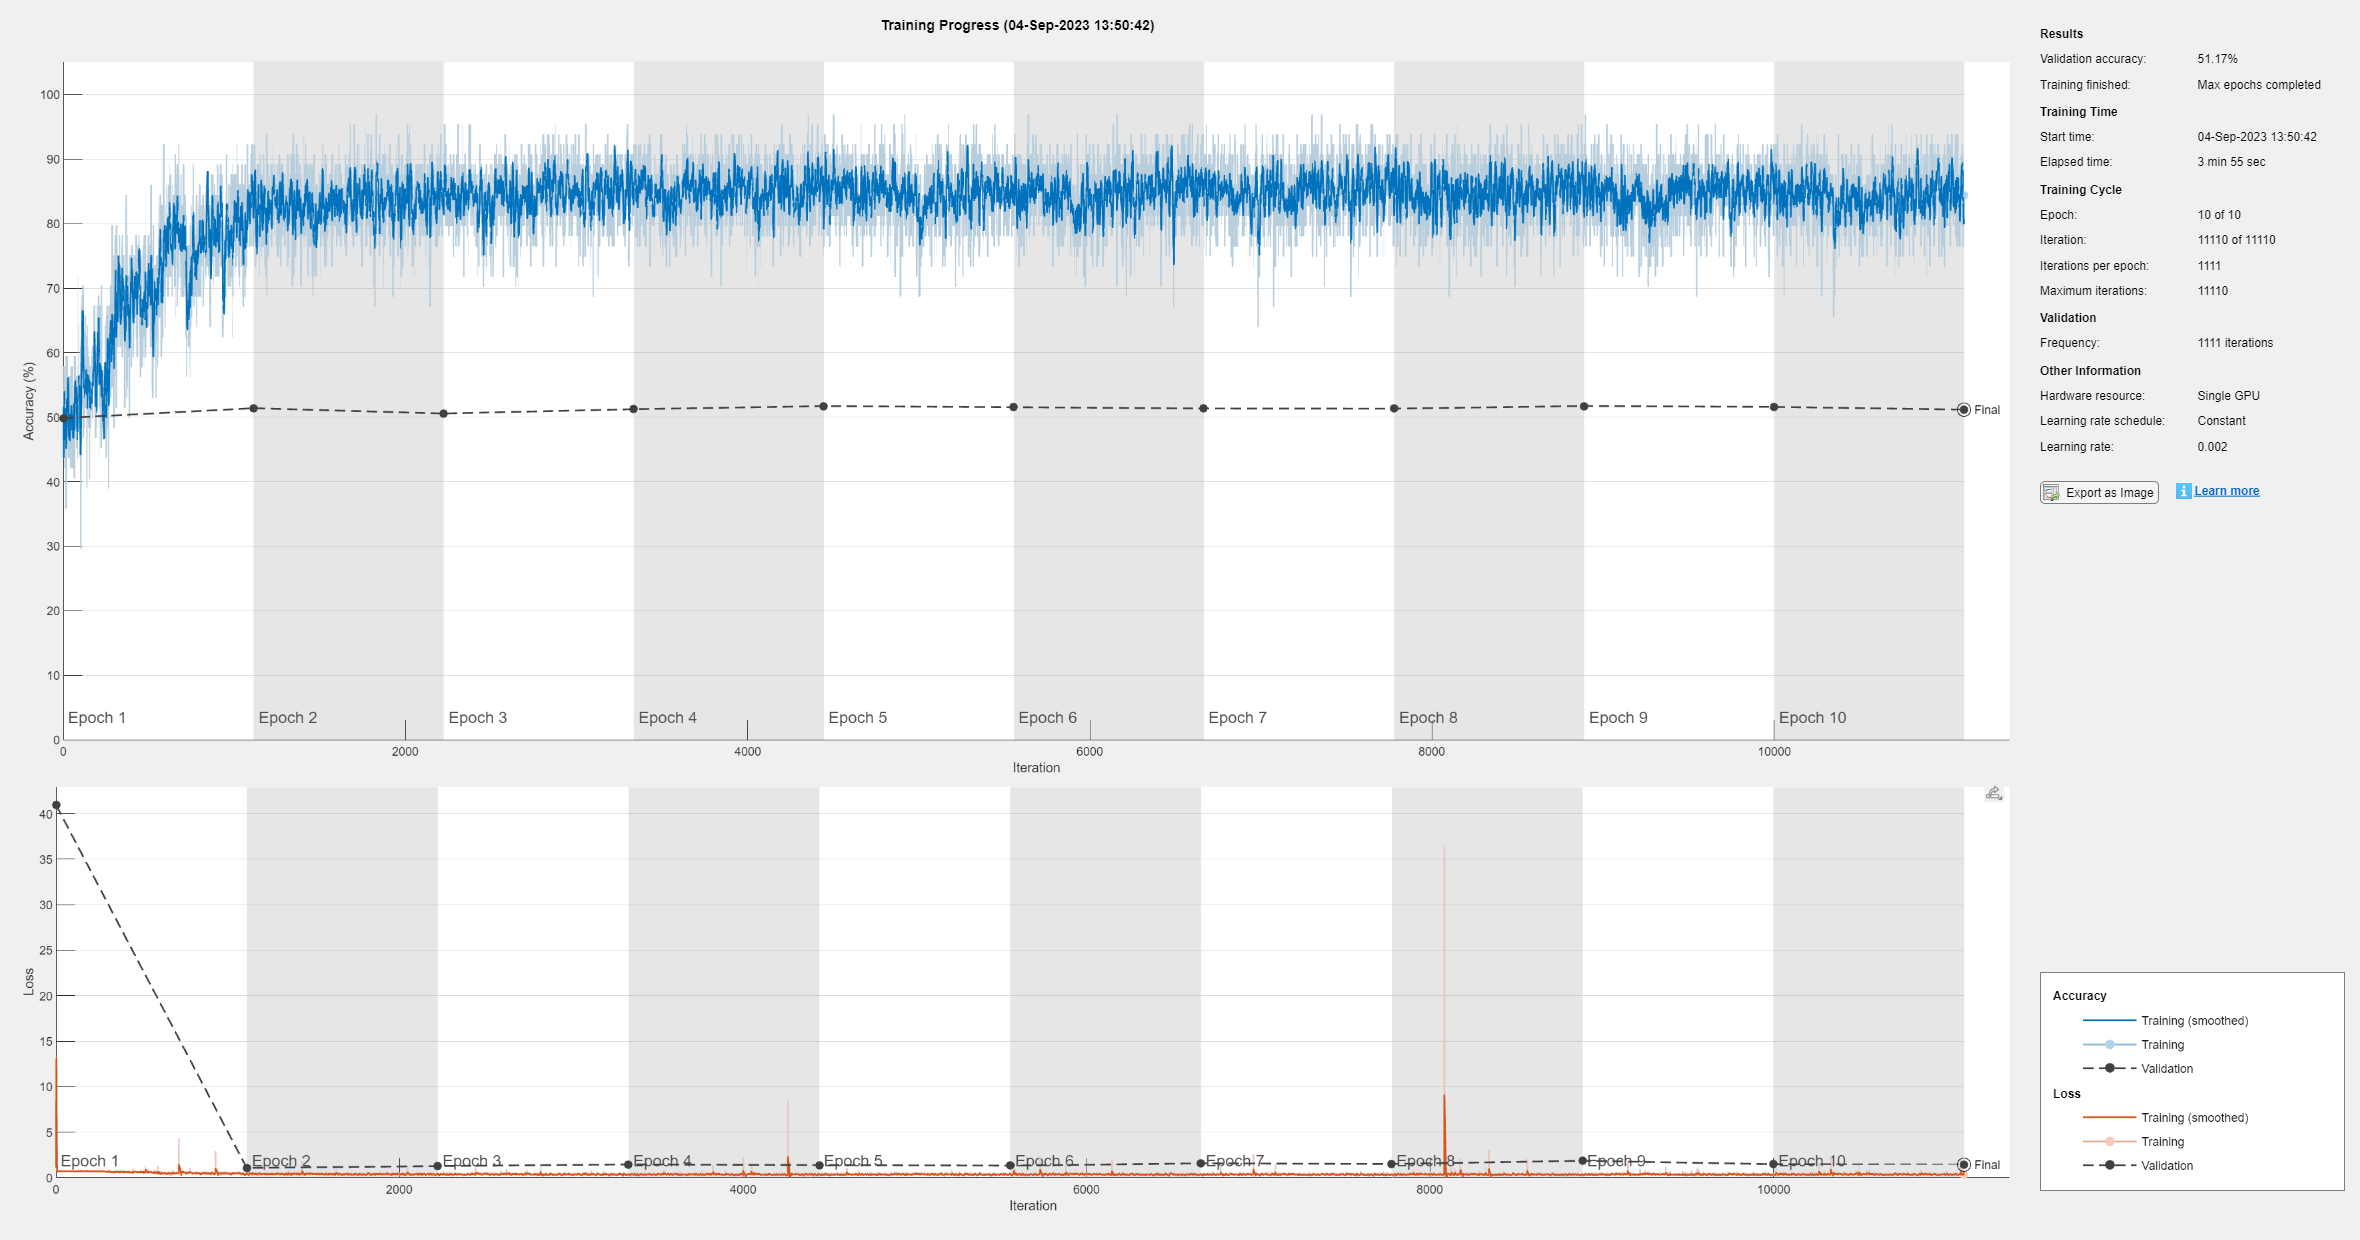

% Training
miniBatchSize = 64; % power of 2
valFreq = floor(length(train_data)/miniBatchSize);
options = trainingOptions('adam', ...
            'InitialLearnRate',0.002, ...
            'SquaredGradientDecayFactor',0.99, ...
            'MaxEpochs',10, ...
            'MiniBatchSize',miniBatchSize, ...
            'Plots','training-progress',...
            'ValidationData',ads_val, ...
            'ValidationFrequency', valFreq);
array_net = trainNetwork(ads_train,layers,options);

## Testing Trained Network

y_pred = classify(array_net, ads_test);

% Accuracy 
acc = mean(y_pred == lblcat_test);
disp(acc*100)

   48.6154

